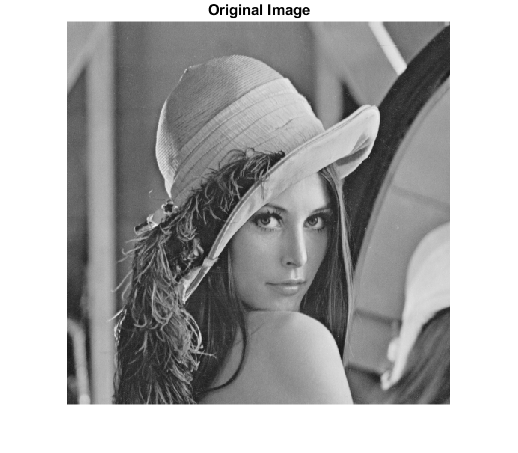

% Histogram Equalization
% a
I = im2uint8(rgb2gray(imread("lena_std.tif")));
imshow(I), title("Original Image");

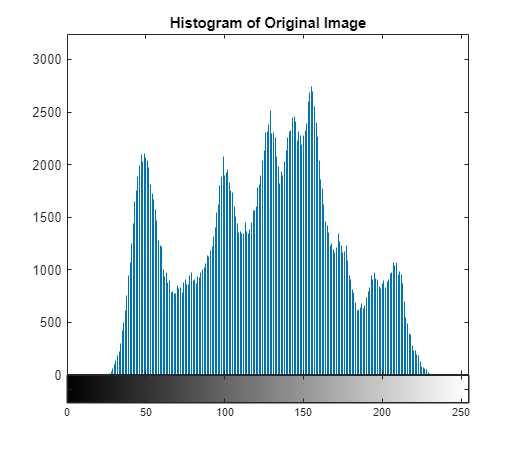


% b
imhist(I), title("Histogram of Original Image");

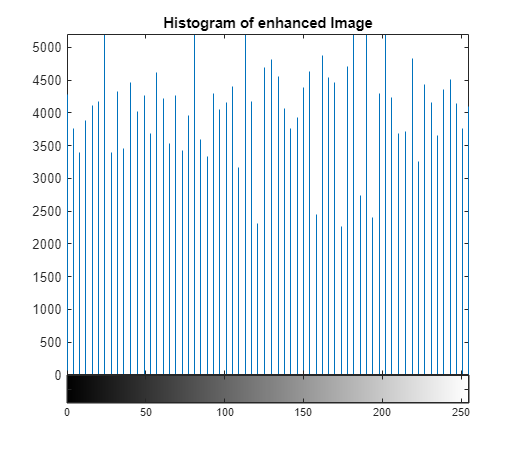


% c
img_he = histeq(I);
imhist(img_he), title("Histogram of enhanced Image");

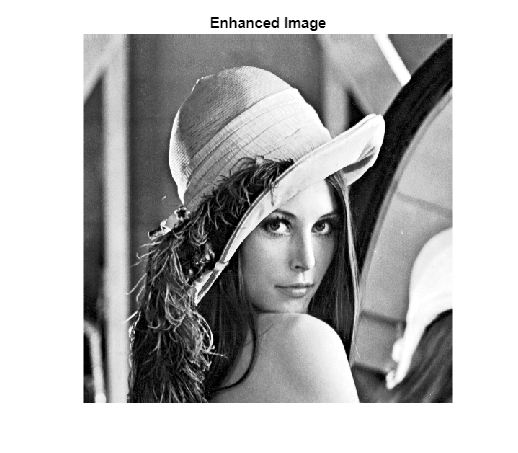

imshow(img_he), title("Enhanced Image");

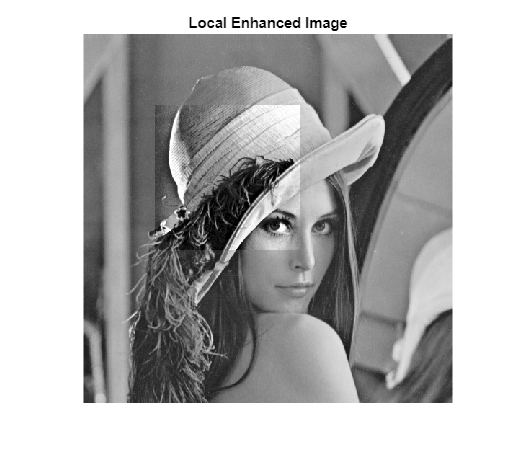


% local enhancement approach
ROI = [100,300,100,300];
loc_he = I;
loc_he(ROI(1):ROI(2),ROI(3):ROI(4)) = histeq(I(ROI(1):ROI(2),ROI(3):ROI(4)));
imshow(loc_he), title("Local Enhanced Image");

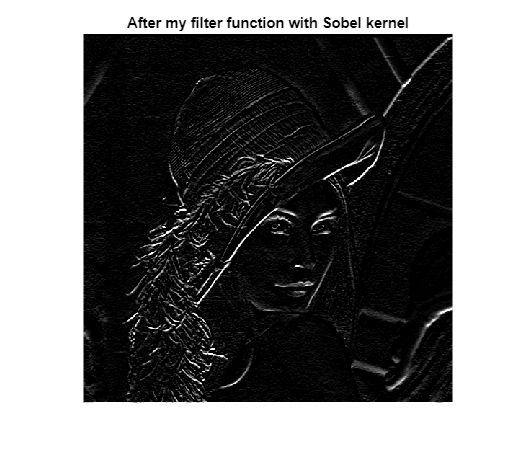


% Filtering
% a
h = fspecial('sobel');
aft_my_fil = myFilter(I,h);
imshow(aft_my_fil), title("After my filter function with Sobel kernel");

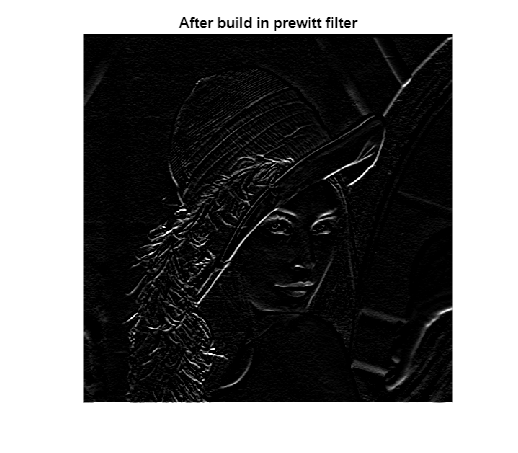


% b
% Prewitt filter
aft_pre = imfilter(I,fspecial('prewitt'));
imshow(aft_pre), title("After build in prewitt filter");

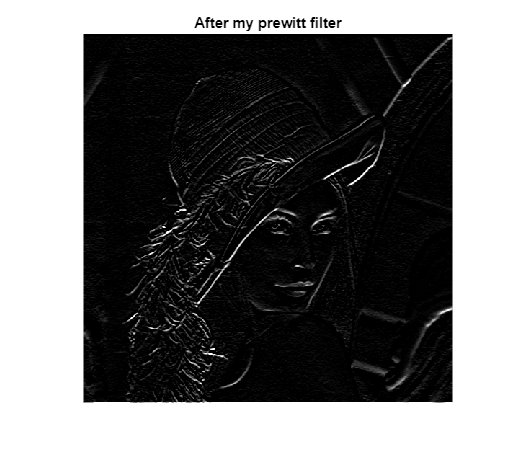

aft_pre_my = myFilter(I,fspecial('prewitt'));
imshow(aft_pre_my), title("After my prewitt filter");

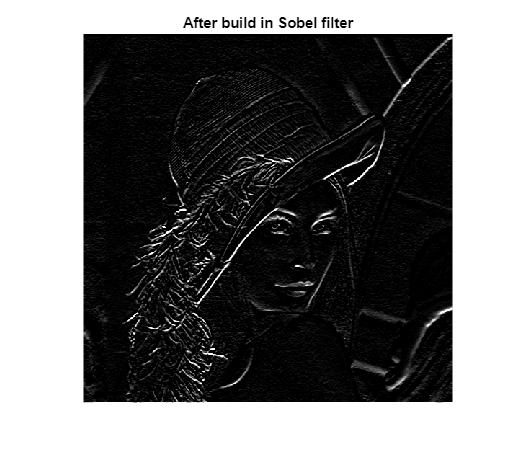

% Sobel filter
aft_sob = imfilter(I,fspecial('sobel'));
imshow(aft_sob), title("After build in Sobel filter");

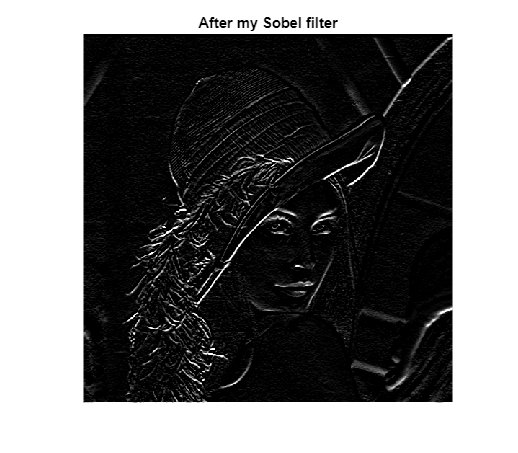

aft_sob_my = myFilter(I,fspecial('sobel'));
imshow(aft_sob_my), title("After my Sobel filter");

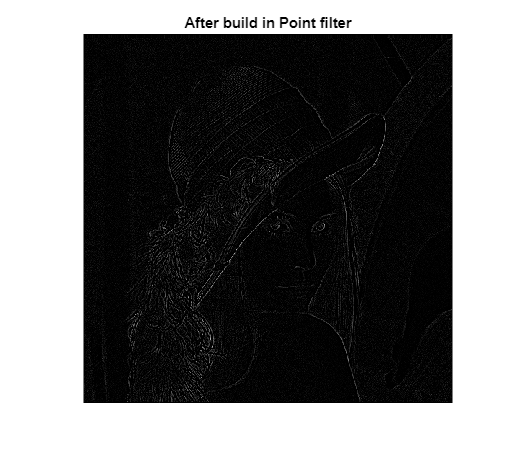

% Point filter
point_f = [1 1 1;1 -8 1;1 1 1];
aft_poi = imfilter(I,point_f);
imshow(aft_poi), title("After build in Point filter");

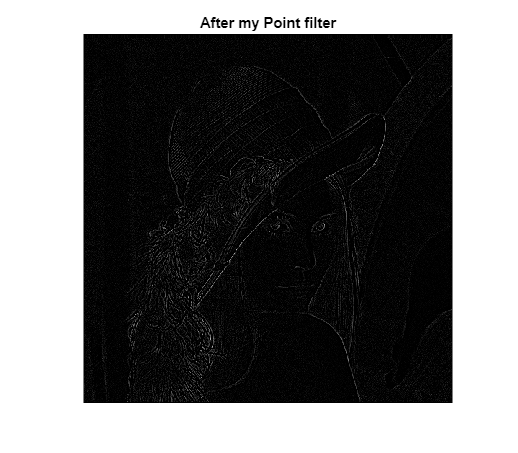

aft_poi_my = myFilter(I,point_f);
imshow(aft_poi_my), title("After my Point filter");

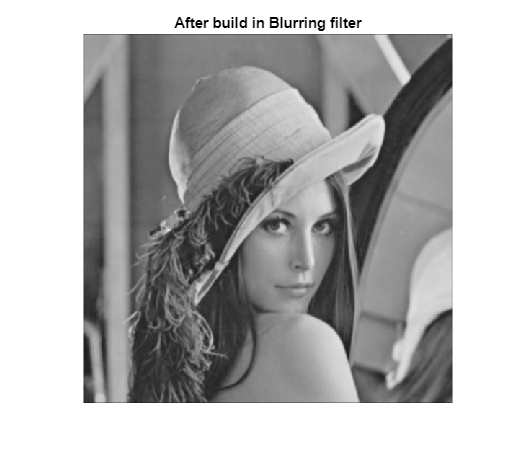

% Blurring filter
aft_blu = imfilter(I,fspecial('gaussian',5,1));
imshow(aft_blu), title("After build in Blurring filter");

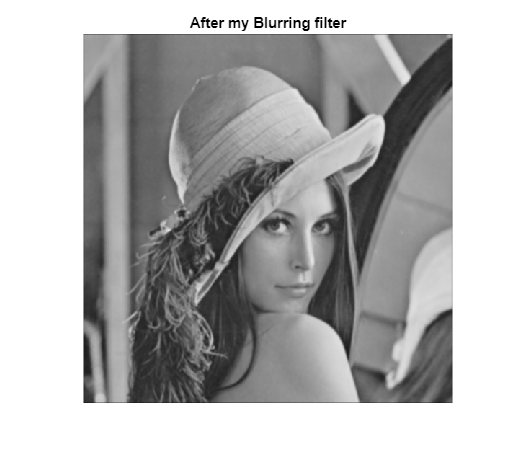

aft_blu_my = myFilter(I,fspecial('gaussian',5,1));
imshow(aft_blu_my), title("After my Blurring filter");

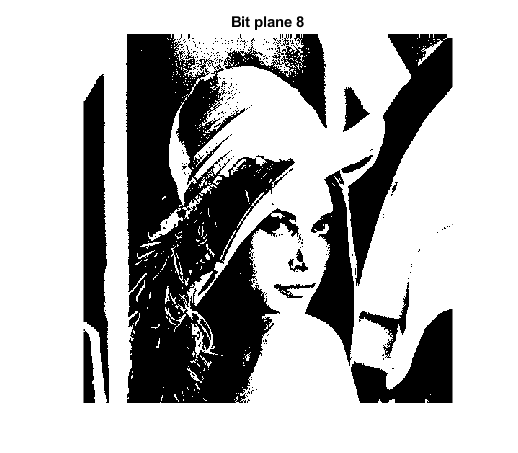


% Bit Plane Splicing
I = im2uint8(rgb2gray(imread("lena_std.tif")));
for i=1:8
    B=logical(bitget(I,i));
    imshow(B);title("Bit plane "+i);
    drawnow;
    pause(0.5);
end

function res = myFilter(I,h)
    % We can add zero padding to original image
    [img_h,img_w] = size(I);
    hsize = size(h);
    padsize = [((hsize(1)-1)/2),((hsize(2)-1)/2)];
    padded_img = zeros(img_h+padsize(1)*2,img_w+padsize(2)*2);
    padded_img(padsize(1)+1:img_h+padsize(1), ...
        padsize(2)+1:img_w+padsize(2)) = I;
    [padded_h,padded_w] = size(padded_img);
    for i=1:img_h
        for j=1:img_w
            copy(i+padsize(1),j+padsize(2)) = sum(sum( ...
                padded_img(i:i+hsize(1)-1,j:j+hsize(2)-1).*h));
        end
    end
    res = uint8(copy(1+padsize(1):padded_h-padsize(1), ...
        1+padsize(2):padded_w-padsize(2)));
end